clc; clearvars; close all;

%% ------------------------------------------------------------------------
% 1) Paths
project_root = './';  % adjust as needed
addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'data'));
disp('✅ Library and data paths added successfully.');

✅ Library and data paths added successfully.



%% ------------------------------------------------------------------------
% 2) Input torques (u = [tau_r; tau_l; tau_1; tau_2; tau_3]) N. m
%   We'll make joint1 torque vary with time to see coupling clearly.
% u_fun = @(t, q, eta_dot) [0.0; 0.0; 0.0; 0.0; 0.0];
u_fun = @(t, q, eta_dot) [0.2; 0.5; 0.0; 0.0; 0.0];
% u_fun = @(t, q, eta_dot) [1.*(t<=5);0; 0.0; 0.0; 0.0];
% u_fun = @(t,q,eta_dot) [0.2; 0.2; 0.5*sin(2*pi*0.5*t); 0; 0];
% u_fun = @(t,q,eta_dot) [0.2; 0.2; 0; 0.5*sin(2*pi*0.5*t); 0];
% u_fun = @(t,q,eta_dot) [0.2; 0.2; 0; 0; 0.5*sin(2*pi*0.5*t)];

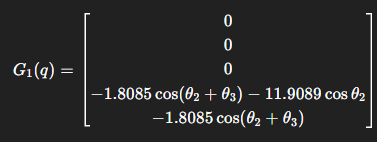

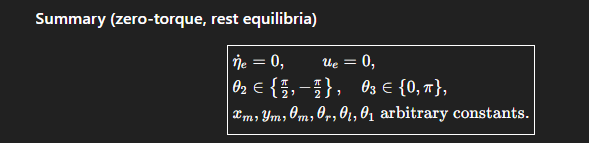

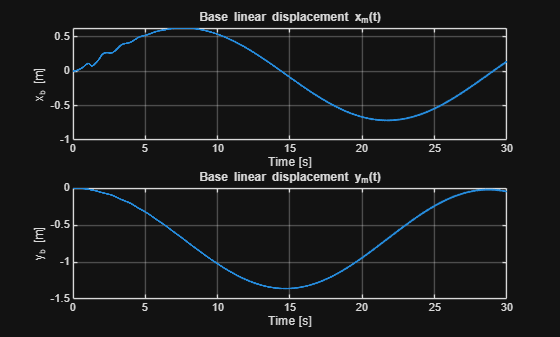

%% ------------------------------------------------------------------------
% 3) Initial state X0 = [q; eta_dot]
% q = [x_b; y_b; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
% eta_dot = [theta_r_dot; theta_l_dot; theta_1_dot; theta_2_dot; theta_3_dot]
X0 = zeros(8 + 5, 1);   % start at rest, all angles = 0
X0(7,1) = -pi/2;
X0(8,1) = 0;
% X0(8,1) = pi;
%% ------------------------------------------------------------------------
% 4) Simulate
tspan = [0 30];
opts = odeset('RelTol',1e-9,'AbsTol',1e-9);
[t,X] = ode45(@(t,X) mm_forward_dynamics_reduced(t,X,u_fun), tspan, X0, opts);
% [t, X] = ode45(@(t,X) mm_forward_dynamics_reduced(t, X, u_fun), tspan, X0);

q_traj       = X(:, 1:8);
eta_dot_traj = X(:, 9:end);

%% ------------------------------------------------------------------------
% 5) Compute torques over time
u_vals = zeros(length(t), 5);
for k = 1:length(t)
    qk       = q_traj(k,:)';
    eta_dotk = eta_dot_traj(k,:)';
    u_vals(k,:) = u_fun(t(k), qk, eta_dotk);
end

%% ------------------------------------------------------------------------
% Indices
ix_x   = 1;
ix_y   = 2;
idx_ang = [3,4,5,6,7,8];  % theta_m, theta_r, theta_l, theta_1, theta_2, theta_3

%% 1) Wrap angular positions in [0, 2*pi)
q_traj_wrapped = q_traj;
q_traj_wrapped(:, idx_ang) = mod(q_traj(:, idx_ang), 2*pi);

%% 2) Base linear motion vs time (keep separate)
figure;
subplot(2,1,1);
plot(t, q_traj(:, ix_x), 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('x_b [m]');
title('Base linear displacement x_m(t)');
grid on;

subplot(2,1,2);
plot(t, q_traj(:, ix_y), 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('y_b [m]');
title('Base linear displacement y_m(t)');
grid on;

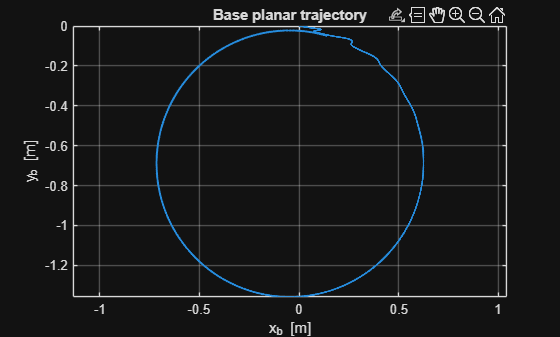


%% 3) Base planar trajectory x–y (keep this!)
figure;
plot(q_traj(:, ix_x), q_traj(:, ix_y), 'LineWidth', 1.5);
xlabel('x_b [m]'); ylabel('y_b [m]');
axis equal; grid on;
title('Base planar trajectory');

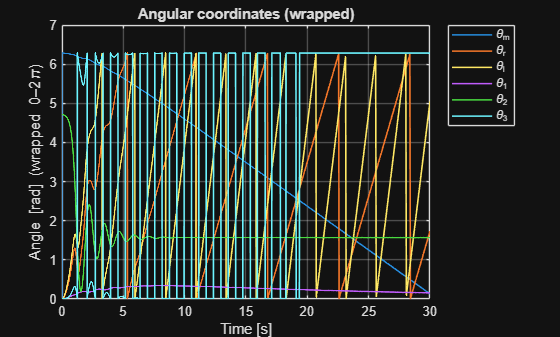


%% 4) Angular coordinates (wrapped)
figure;
plot(t, q_traj_wrapped(:, idx_ang), 'LineWidth', 1.2);
xlabel('Time [s]');
ylabel('Angle [rad] (wrapped 0–2\pi)');
legend({'\theta_m','\theta_r','\theta_l','\theta_1','\theta_2','\theta_3'}, ...
       'Location','bestoutside');
grid on;
title('Angular coordinates (wrapped)');

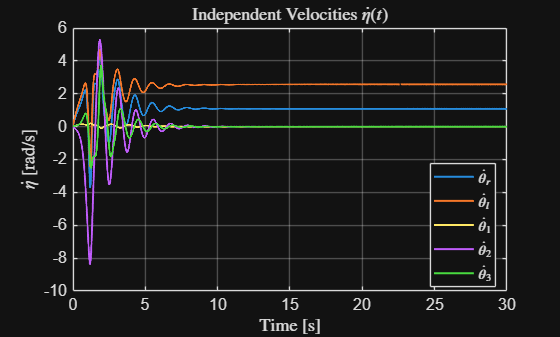


%% 5) Independent velocities \eta_dot(t) 
figure;
%% 5) Independent velocities η̇(t)
figure;
plot(t, eta_dot_traj, 'LineWidth', 1.5);

xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('$\dot{\eta}$ [rad/s]', 'Interpreter', 'latex');
title('Independent Velocities $\dot{\eta}(t)$', 'Interpreter', 'latex');

grid on;
legend({ ...
    '$\dot{\theta}_r$', ...
    '$\dot{\theta}_l$', ...
    '$\dot{\theta}_1$', ...
    '$\dot{\theta}_2$', ...
    '$\dot{\theta}_3$' ...
    }, 'Interpreter', 'latex', 'Location', 'best');

set(gca, 'FontSize', 12, 'Box', 'on');

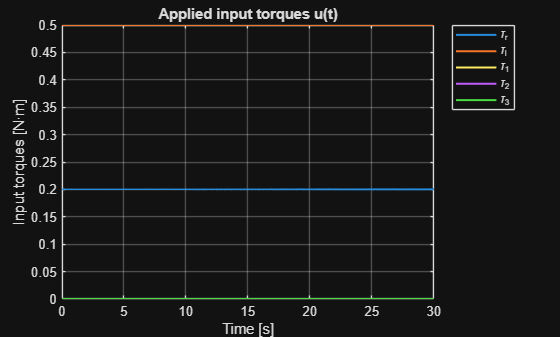



%% 6) Applied input torques
figure;
plot(t, u_vals, 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Input torques [N·m]');
grid on;
legend({'\tau_r','\tau_l','\tau_1','\tau_2','\tau_3'}, 'Location','bestoutside');
title('Applied input torques u(t)');